# Exercise 2

`Define with vector parameters (not DH) the refrence frames of the robot.`

We have to find the following:

- joint-joint transformations

- base to end-effector transformations

- plot the reference frames

- GUI

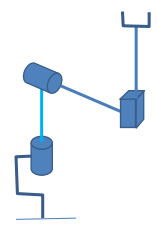

- rot z

- rot x

- transl y

import plotFrame.*;

clear all;

h0 = 2;
h1 = 4;
theta1 = pi/3;
l2 = 3;
theta2 = pi/12;

b0 = [0 0 h0]';
b1 = [0 0 h1]';
b2 = [0 l2 0]';

H10 = [rotz(rad2deg(theta1)) b0;
       zeros(1, 3) 1];
H21 = [rotx(rad2deg(theta2)) b1;
       zeros(1, 3) 1];
H32 = [eye(3) b2;
       zeros(1, 3) 1];

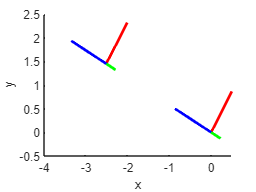

clf;
hold on;
plotFrame(H10);
plotFrame(H10*H21);
plotFrame(H10*H21*H32);
xlabel('x');
ylabel('y');
zlabel('z');